We compute SSM for an Oscillator Chain with cubic and quadratic nonlinearities as follows

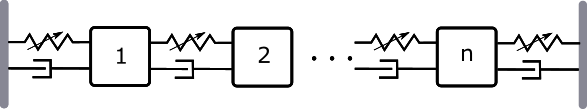

Here we focus on the transient dynamics of such a system. Specifically, the excitation is set to be zero and we calculate the response of full system and reduced systems obtained with SSM analysis.

clear all; close all; clc

## Example setup

n = 2;    % number of oscillators
mass = 1;  % mass
k = 1;     % stiffness
c = 0.1;   % damping
kappa2 = 0;   % quadratic nonlinearity
kappa3 = 0.75; % cubic nonlinearity
% kappa3 = 0; % cubic nonlinearity = 0

[K,C,f2,f3] = assemble_global_coefficients(k,kappa2,kappa3,c,n);

Dirichlet boundary conditions

K = K(2:n+1,2:n+1);
C = C(2:n+1,2:n+1);
M = mass*speye(n,n);
f3 = f3(2:n+1,2:n+1,2:n+1,2:n+1);

#### Dynamical System Setup

Consider the following forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}({\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}({\phi}),\\\dot{\phi}	
=\Omega$$


where 


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',{[],f3});
set(DS.Options,'Emax',4,'Nmax',20,'notation','multiindex')
outdof = [1 2];
outdof = floor(outdof);
outdof = outdof(outdof>0);
set(DS.Options, 'outDOF', outdof);

Add external forcing and also control matrix

Bext     = zeros(n,1); Bext(1,1)=1;
% ExtForce = @(t) Bext*[sin(0.1*sqrt(2)*t);3*cos(0.1*sqrt(3)*t)];
ExtForce = @(t) Bext*sin(0.1*sqrt(2)*t);
epsilon  = 1e-3;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

#### Linear Modal analysis

We solve generalized eigenvalue problem


$$\mathbf{A}\mathbf{V}=\mathbf{B}\mathbf{V}\mathbf{D}$$


where $\mathbf{V}=(\mathbf{v}_1,\cdots,\mathbf{v}_n)$ and $\mathbf{D}=\mathrm{diag}\{\lambda_1,\cdots,\lambda_n\}$ such that $\mathbf{A}\mathbf{v}_i=\lambda_i\mathbf{B}\mathbf{v}_i$. We also calculate the left eigenvectors $\mathbf{W}=(\mathbf{w}_1,\cdots,\mathbf{w}_n)$ such that

$\mathbf{W}^\ast\mathbf{A}=\mathbf{D}\mathbf{W}^\ast\mathbf{B}$.

The eigenvectors are normalized in the folowing way

$\mathbf{W}^\ast\mathbf{B}\mathbf{V}=\mathbb{I}$.

[V,D,W] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i
  -0.1500 + 1.7255i
  -0.1500 - 1.7255i


## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 3;

**Reduced dynamics simulation**

*Construction of initial condition*

% master subspace
modes = [1 2];
S.choose_E(modes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2
These are in resonance with the follwing eigenvalues of the master subspace
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i
sigma_in = 3


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.92E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.06E-03 MB


% construct initial condition
p0 = [0.5 0.5]';
z0 = reduced_to_full(p0,W_0,[],0)+0.;


## Linear model order reduction analysis

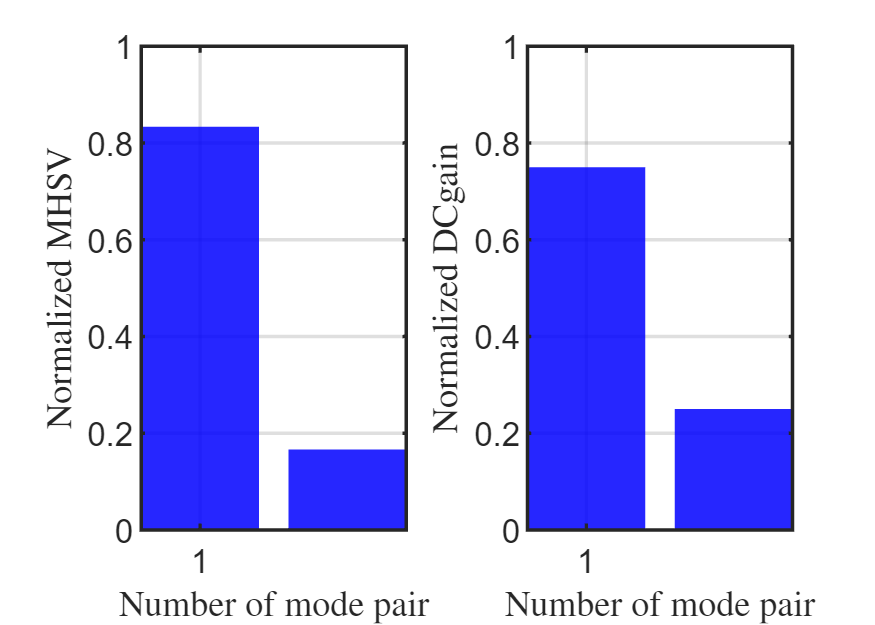

MHSV sum of the first 2 pairs
     1
DCgain sum of the first 2 pairs
     1


res = Linear_MOR(DS,n);

tf     = 20;
nsteps = 1000;
% for closed-loop solution, the computational time increases significantly
% when the number of grid points increases. (when interp1 is called).
% if we use griddedInterpolant, this will be ...
auData = construct_autoData(DS, modes, R_0);

cont   = struct();
cont.Q    = blkdiag(5e3*eye(n),zeros(n));
cont.Rhat = 0.01*eye(1);
cont.Mhat = 0*eye(2*n);
cont.zd   = [];


## Free vibration - without control

om = 2*pi/tf;
% κ_3 > 0
[tfullwoNL, xfullwoNL] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
% % % % save("tfullwoNL.mat","tfullwoNL")
% % % % save("xfullwoNL.mat","xfullwoNL")

% κ_3 = 0
% [tfullwoL, xfullwoL] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z0);
% save("tfullwoL.mat","tfullwoL")
% save("xfullwoL.mat","xfullwoL")


## Comparison free vibration: κ_3=0， κ_3=0.75

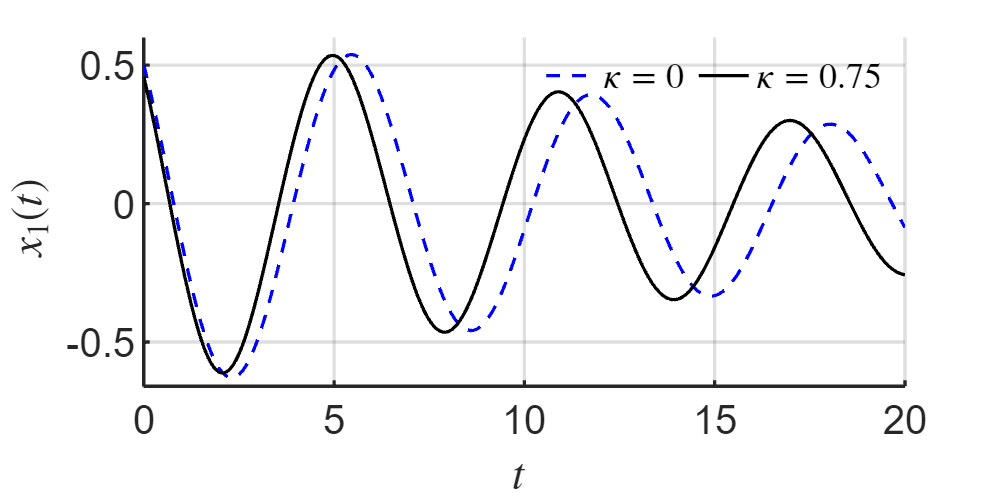

% You should set κ3=0, run the code and save the data as xfullwoL
% Then set κ3=0.75, run the code
load("tfullwoL.mat","tfullwoL")
load("xfullwoL.mat","xfullwoL")


figure; hold on
plot(tfullwoL, xfullwoL(:,1),'b--','DisplayName', '$\kappa=0$','LineWidth',2);
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', '$\kappa=0.75$','LineWidth',2);

xlabel('$t$ ','Interpreter',"latex")
ylabel('$x_1(t)$ ','Interpreter',"latex")

legend('show','Interpreter',"latex",'Orientation','horizontal'); legend boxoff
set(gca,'FontSize',24);
grid on
axis tight
ylim([-0.66,0.6])
set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);

% print('-depsc', 'OscillatorChain_ControlPolicy_outdof5_woFeedback.eps')
% print -djpeg -r300 OscillatorChainKappa.jpg;


## Open loop control

t0 = 0;
t1 = tf;

tspan = linspace(t0,t1,nsteps);
traj_open = LQR_closed_loop(DS,z0,'linear',tspan,auData,W_0,modes,1:4,cont);

pl
   0.5046 + 0.0470i
   0.5046 - 0.0470i
p0
   0.5046 + 0.0470i
   0.5046 - 0.0470i
历时 0.041401 秒。
历时 0.057261 秒。
Time for backward simulation of Riccati ODE is 6.011250e-02
历时 0.253425 秒。
Time for backward simulation of compensated ODE is 4.256244e-01
历时 0.400300 秒。
Time for forward simulation of ODEs for modal coordinates is 4.017167e-01



om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj_open.time,traj_open.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

**plot**

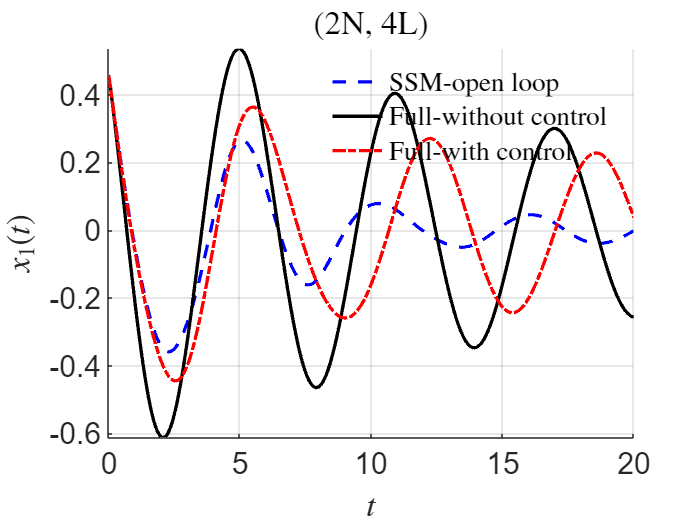

% displacement field
figure; hold on

plot(traj_open.time, traj_open.zt(1,:),'b--','DisplayName','SSM-open loop','LineWidth',2);
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfullwc1, xfullwc1(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',18);
grid on, axis tight

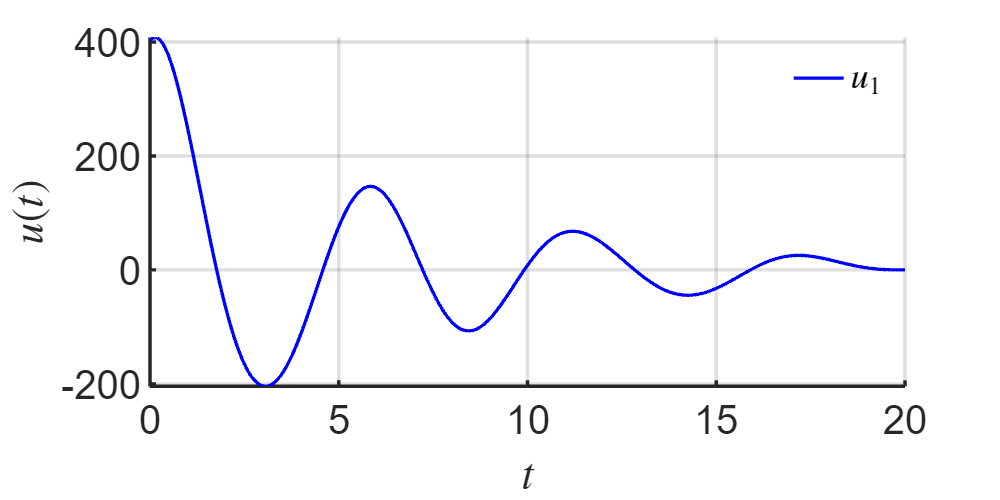





%  control input
figure; hold on;
plot(traj_open.time,traj_open.ut,'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);

legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',24); grid on, axis tight

set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);

% print('-depsc', 'OscillatorChain_ControlPolicy_outdof5_woFeedback.eps')
% print -djpeg -r300 OscillatorChain_ControlPolicy_outdof5_woFeedback.jpg;


## Closed loop control

**Full dynamics simulation - with control**

t0 = 0;
t1 = tf/4; % 5s
t2 = tf;   % 20s

**Time interval - 1**

om = 2*pi/t1;
tspan1 = linspace(t0,t1,nsteps);
traj_closed1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,modes,1:4,cont);

pl
   0.5046 + 0.0470i
   0.5046 - 0.0470i
p0
   0.5046 + 0.0470i
   0.5046 - 0.0470i
历时 0.016419 秒。
历时 0.023556 秒。
Time for backward simulation of Riccati ODE is 2.380400e-02
历时 0.059134 秒。
Time for backward simulation of compensated ODE is 6.108210e-02
历时 0.041827 秒。
Time for forward simulation of ODEs for modal coordinates is 4.330100e-02



ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1,xf,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

xf  = xf'; % initial for next interval

#### Time interval - 2

tspan2 = linspace(t1,t2,nsteps);
traj_closed2 = LQR_closed_loop(DS,xf,'linear',tspan2,auData,W_0,modes,1:4,cont);

pl
   0.1164 - 0.2072i
   0.1164 + 0.2072i
p0
   0.1164 - 0.2072i
   0.1164 + 0.2072i
历时 0.021743 秒。
历时 0.019711 秒。
Time for backward simulation of Riccati ODE is 1.997830e-02
历时 0.122495 秒。
Time for backward simulation of compensated ODE is 1.246716e-01
历时 0.265111 秒。
Time for forward simulation of ODEs for modal coordinates is 2.668894e-01



om = 2*pi/(t2-t1);
ufun = @(t) transpose(interp1(traj_closed2.time,traj_closed2.ut',t));
set(DS,'u',ufun);
[tfullwc2, xfullwc2,~,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',xf,'ts',t1);


### Plot - oscillator 1

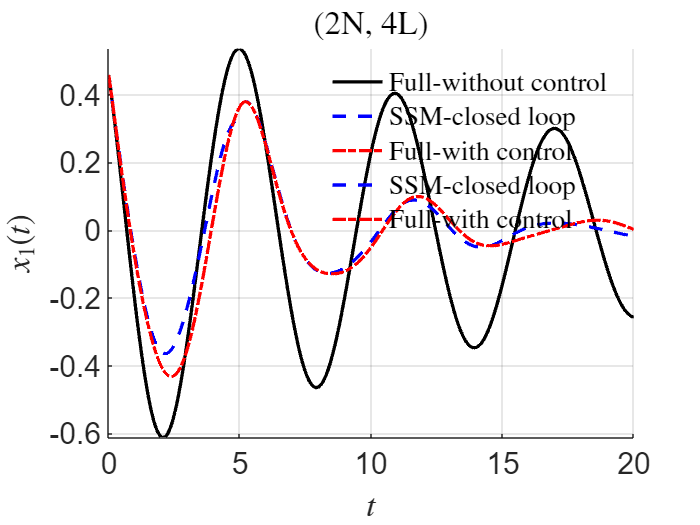

figure; hold on
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);

plot(traj_closed1.time, traj_closed1.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc1, xfullwc1(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);

plot(traj_closed2.time, traj_closed2.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc2, xfullwc2(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',18);
grid on, axis tight

### Plot - oscillator 2

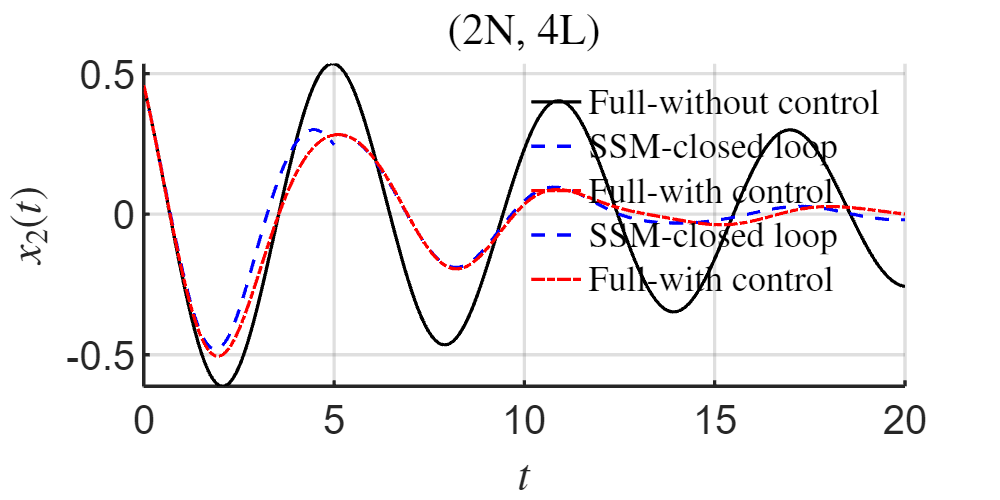

figure; hold on
plot(tfullwoNL, xfullwoNL(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);

plot(traj_closed1.time, traj_closed1.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc1, xfullwc1(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);

plot(traj_closed2.time, traj_closed2.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc2, xfullwc2(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(2)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',24);
grid on


set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);

% print('-depsc', 'OscillatorChain_outdof5_woFeedback.eps')
% print -djpeg -r300 OscillatorChain_outdof5_woFeedback.jpg;


## Plot - control inputs

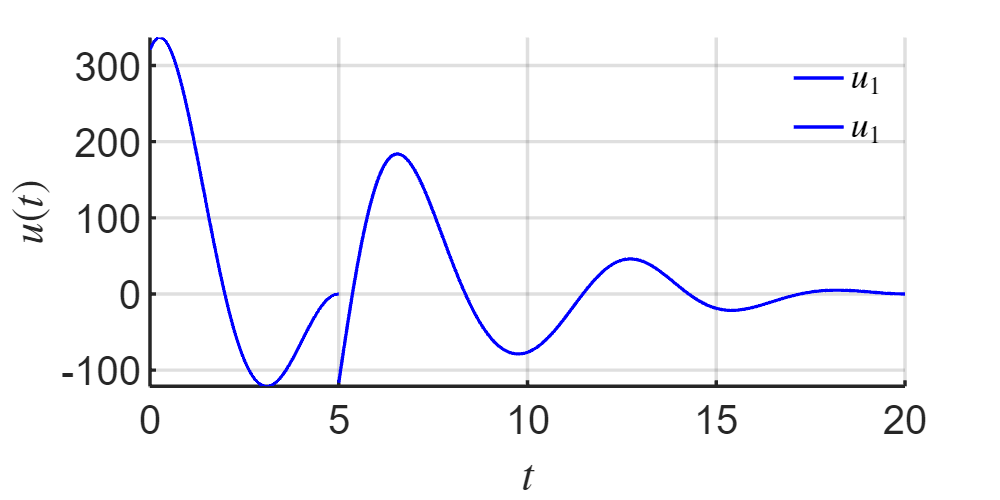

%  control input
figure; hold on;
plot(traj_closed1.time,traj_closed1.ut(1,:),'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);

plot(traj_closed2.time,traj_closed2.ut(1,:),'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);

legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',24); grid on, axis tight

set(gca, 'LineWidth', 2);
set(gcf, 'Position', [0 0 800 400]);